% To investigate the convergence of the functional series 
% u(x,n)=n!/n^n*(x^2-4*x+6)^n
% at points x=1 and x=2.

syms x n;
u(x,n)=(factorial(n)/n^n)*(x^2-4*x+6)^n

$$u(x, n) = \frac{n!\,{\left(x^{2}-4\,x+6\right)}^{n}}{n^{n}}$$


x=1

x = 1

u1(n)=u(x,n)

$$u1(n) = \frac{3^{n}\,n!}{n^{n}}$$

% (3^n*factorial(n))/n^n
D=limit(u1(n+1)/u1(n),n,inf)

$$D = 3\,{\mathrm{e}}^{-1}$$

% 3*exp(-1)
vpa(D)

$$ans = 1.1036383235143269647865713104844$$

% 1.1 > 1 => series diverges

x=2

x = 2

u2(n)=u(x,n)

$$u2(n) = \frac{2^{n}\,n!}{n^{n}}$$

% (2^n*factorial(n))/n^n
D=limit(u2(n+1)/u2(n),n,inf)

$$D = 2\,{\mathrm{e}}^{-1}$$

% 2*exp(-1)
vpa(D)

$$ans = 0.73575888234288464319104754032292$$

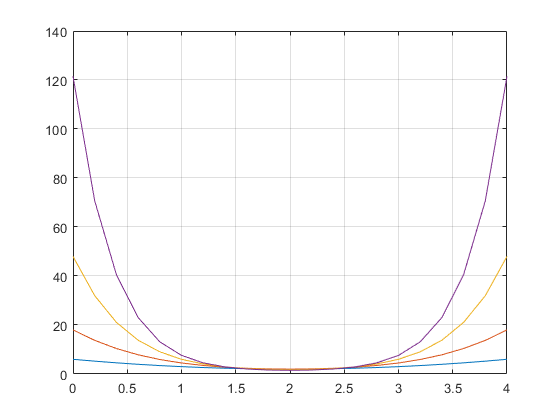

% 0.74 < 1 => the series converges

x1=0:0.2:4;
for i=1:4
    y1=u(x1,i);
    plot(x1,y1)
    hold on
    grid on
end
hold off